# Compressed air storage results

This is the analysis of the results of the compressed air energy storage

load CA_final.mat

d_long.HourDK(1)+years(30)

ans = datetime
   2050-10-01T06:36:00


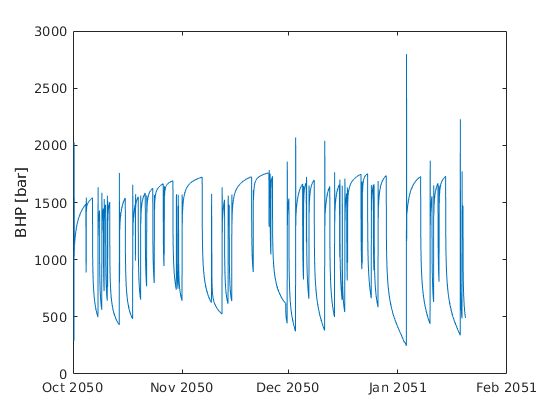

figure(5)
plot(d_long.HourDK(1:end-1)+years(30), p_hist/1e5)
axis normal
ylabel('BHP [bar]')
saveas(gcf, 'CA_p_hist.jpg')

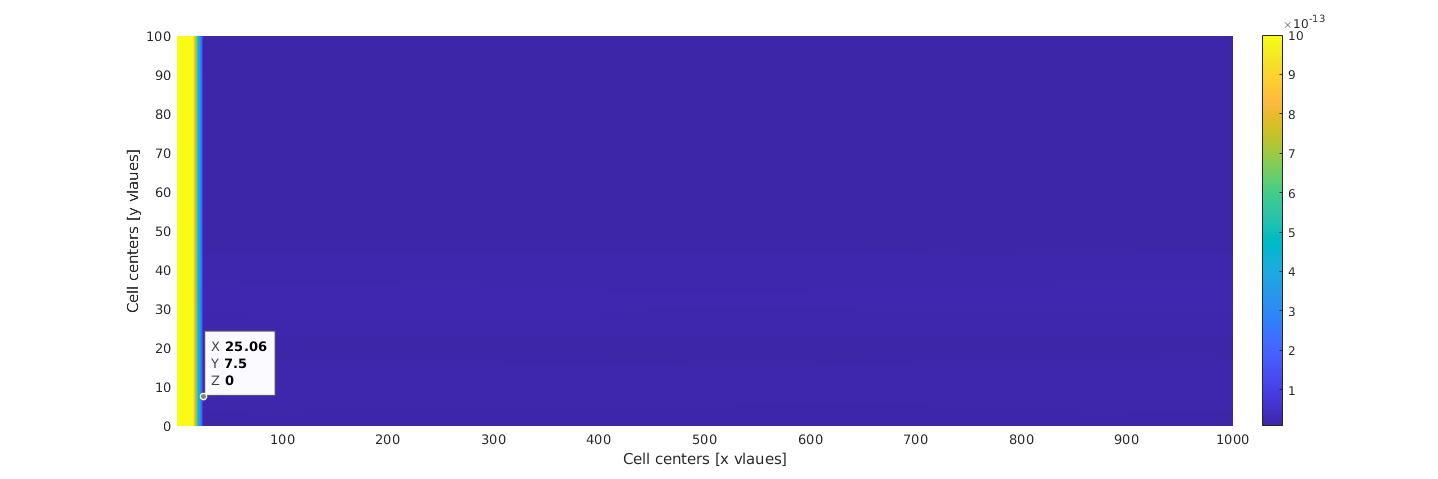

hFig = figure(2);
set(hFig, 'Position', [200 200 1500 500]);
visualizeCells(k); axis normal; shading interp;
saveas(gcf, 'CA_perm_harald.jpg')

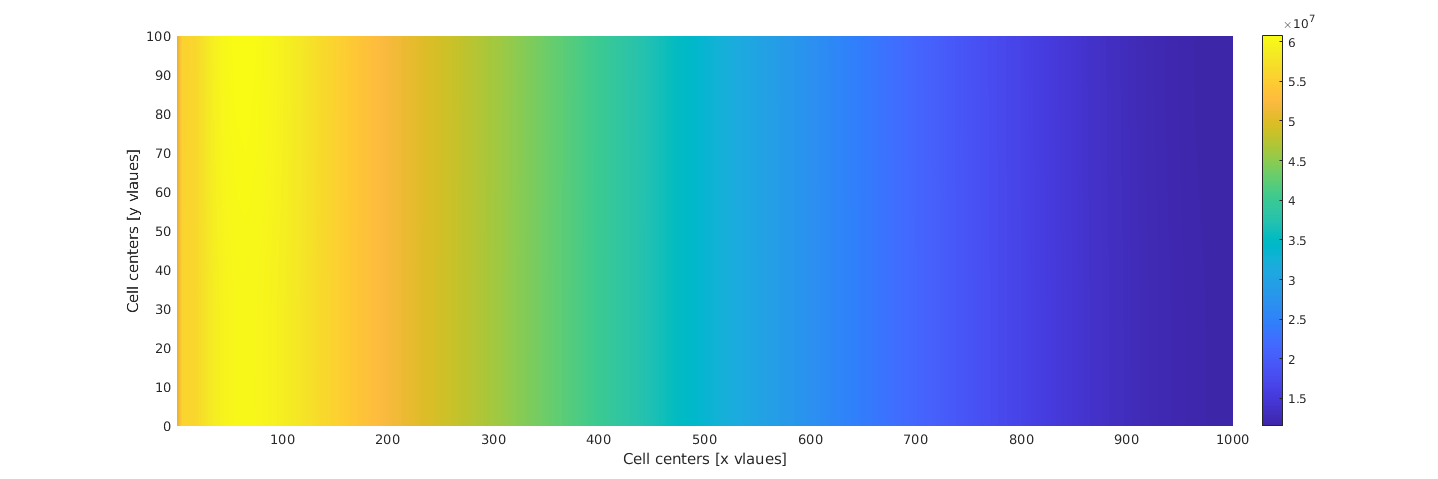

hFig = figure(3);
set(hFig, 'Position', [200 200 1500 500]);
visualizeCells(p_val); shading interp; axis normal;
saveas(gcf, 'CA_pressure_harald.jpg')

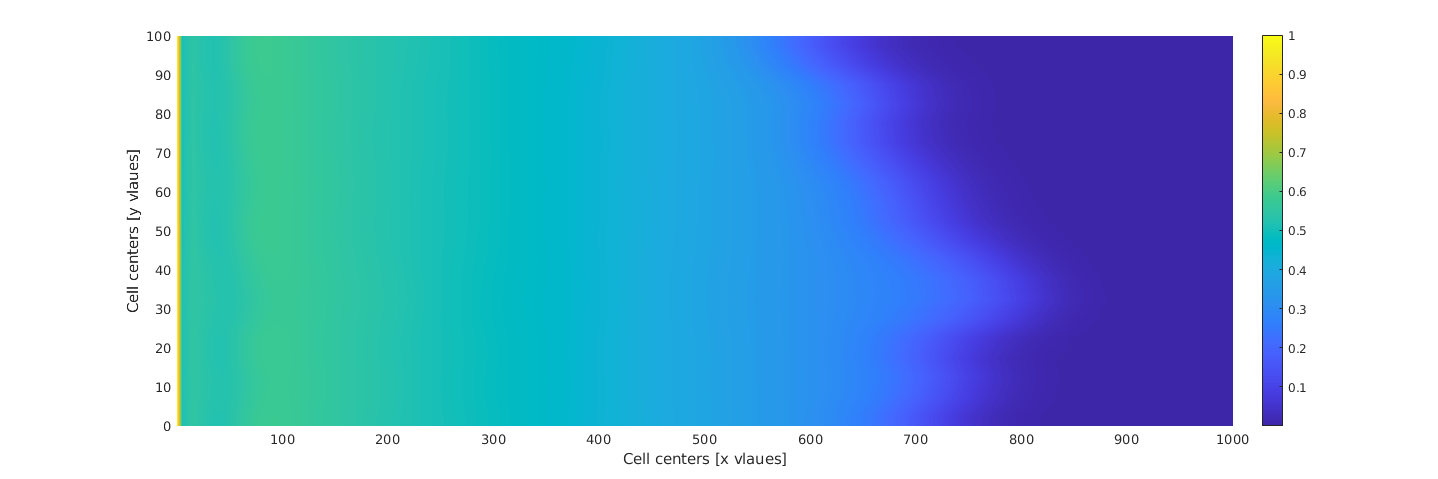

hFig = figure(4);
set(hFig, 'Position', [200 200 1500 500]);
visualizeCells(c_init); shading interp; axis normal;
saveas(gcf, 'CA_tracer_harald.jpg')

consumed_elec = sum((m_hist>0)*elec_max/1e6) % MWh

consumed_elec = 29360

% w_isentropic = compressor_station(p_atm, p_inj, comp_ratio, comp, T_inj);
produced_elec = 0;
for i=1:length(p_hist)
    if m_hist(i)<0
        produced_elec = produced_elec+m_hist(i)*eta_turbine*exergy(p_hist(i), T_ref, 'Air');
    end
end

Unable to resolve the name py.CoolProp.CoolProp.PropsSI.

Error in exergy (line 9)
    H = py.CoolProp.CoolProp.PropsSI('H','P',p,'T',T,comp); % J/mol

produced_elec = -produced_elec/1e6
eff = produced_elec/consumed_elec

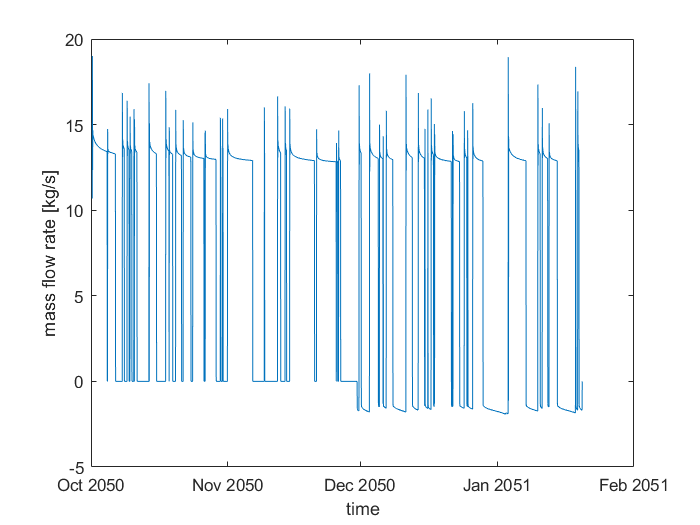

% save the injection and production rates as a csv file
plot(d_long.HourDK+years(30), m_hist)
xlabel('time')
ylabel('mass flow rate [kg/s]')

rate_data = table(d_long.HourDK+years(30), m_hist, 'VariableNames', {'date', 'rate(kg/s)'})

rate_data = 2665×2 table
           date            rate(kg/s)
    ___________________    __________

    2050-10-01T06:36:00      10.686  
    2050-10-01T07:36:00      19.018  
    2050-10-01T08:36:00      12.335  
    2050-10-01T09:36:00      14.707  
    2050-10-01T10:36:00      14.282  
    2050-10-01T11:36:00      14.376  
    2050-10-01T12:36:00      14.296  
    2050-10-01T13:36:00      14.264  
    2050-10-01T14:36:00       14.22  
    2050-10-01T15:36:00      14.182  
    2050-10-01T16:36:00      14.144  
    2050-10-01T17:36:00      14.111  
    2050-10-01T18:36:00      14.081  
    2050-10-01T19:36:00      14.053  
    2050-10-01T20:36:00      14.027  
    2050-10-01T21:36:00      14.002  


writetable(rate_data, 'inj_rate_air.csv')

